Creating the Learning Factory Environment

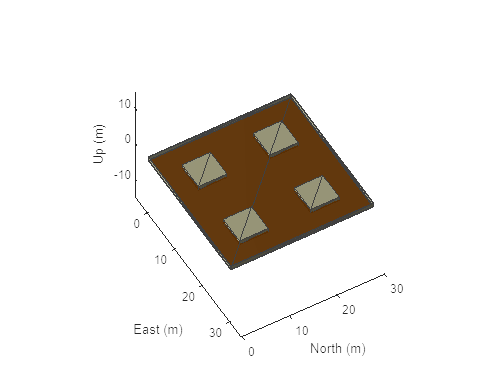

envc = EnvironmentConstants();
[obstacles, scenario, gridSize] = envc.createRobotScenerioEnvironment2();
show3D(scenario);
lightangle(-45,30);
view(60,50);

Reinforcement Learning stuff

points = [];
counter = 0

counter = 0

rng(12)
while counter < 12
    counter = counter + 1;

    isvalid = false;
    while ~isvalid        
        rows = randperm(gridSize(1),1);
        cols = randperm(gridSize(2),1);
        position = [rows' cols'];
        if ~isempty(points)
            if ~any(ismember(position, obstacles, 'rows')) && ~any(ismember(position, points, 'rows')) 
                isvalid = true;
                points = [points; position];
            end
        elseif ~any(ismember(position, obstacles, 'rows')) 
            isvalid = true;
            points = position;
        end
    end
end
points

points =      8    17
     1    28
    28     2
    29     5
     9    19
    29    26
     1    16
    17    15
    23     1
     5     4


fname = sprintf('experiment_points/experiment_2_points', 'points');
save(fname)
 